# *Drosophila* Body dynamics

clear; close all; clc

Body Inertia

I_b = 5.2e-13; % Body Interia [N*m*s^2]
% I_b = 5.9e-13; % Body Interia [N*m*s^2] +- 3.3e-14

Body Damping

C_b = 5.2e-13; % Body Damping [N*m*s]
% C_b = 1.1e-12; % Body Damping [N*m*s] +- 2.3e-11

Time Constant

tau = I_b/C_b; % time constant

Body Plant

G = tf(1,[tau 1])


G =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



Delay Simulations

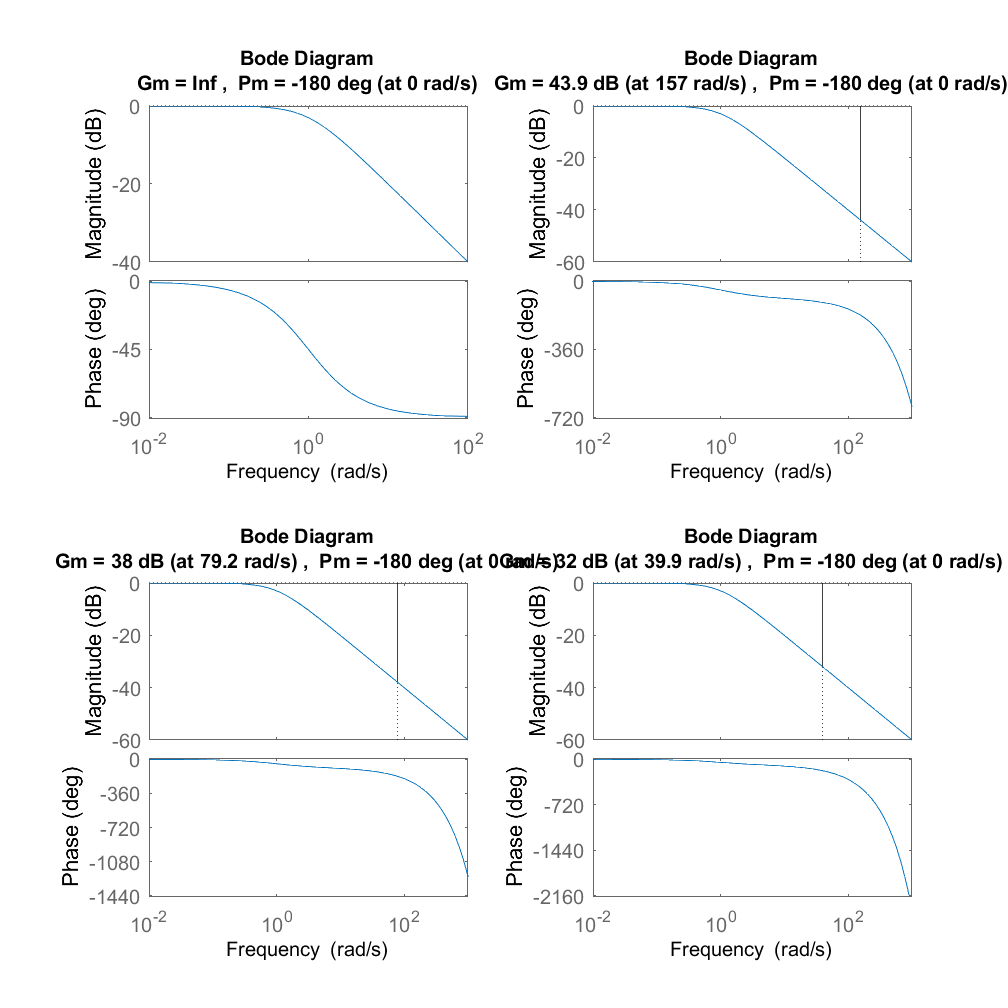

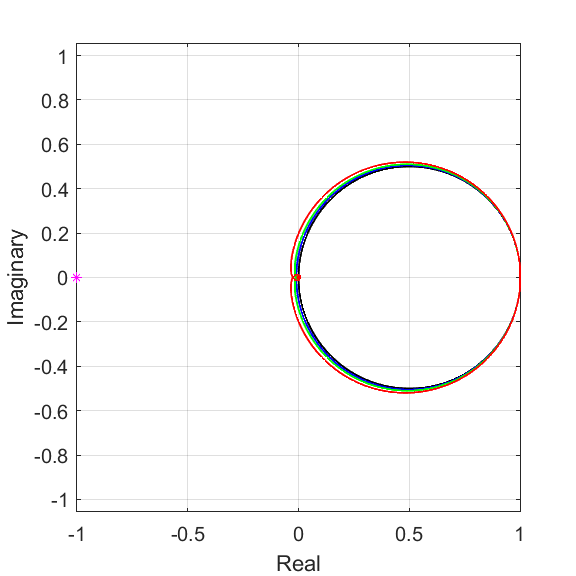

delay = [0 10 20 40]*10^(-3);
freq = linspace(0,1000,500000)';

fig(1) = figure (1) ; clf
fig(2) = figure (2) ; clf
fig(3) = figure (3) ; clf
set(fig,'Color','w','Units','inches')

fig(1).Position = [2 2 5 5];
fig(2).Position = [2 2 7 7];
fig(3).Position = [2 2 4 4];

CC = {'k','b','g','r','c'};
for kk = 1:length(delay)
    G = tf(1,[tau 1]);
    G.IODelay = delay(kk);
%     G = feedback(G,1);
    [mag,phase,wout] = bode(G,2*pi*freq);
    mag = squeeze(mag);
    phase = squeeze(phase);
    wout = squeeze(wout)./(2*pi);
    
    [Gm,Pm,Wcg,Wcp] = margin(G);
    % Gm = 20*log10(Gm);
    Wcg = Wcg/(2*pi);
    Wcp = Wcp/(2*pi);
    Gm = 1/Gm;
    
    figure (1)
    ax(1) = subplot(2,1,1) ; hold on
    plot(wout,mag,'-','Color',[0.5 0.5 0.5],'LineWidth',1)
%     plot(Wcg,Gm/100,'*','Color',CC{kk})
    
    ax(2) = subplot(2,1,2) ; hold on
    plot(wout,phase,'-','Color',CC{kk},'LineWidth',1)
    plot(Wcg,-180,'o','Color','k','MarkerSize',5)
    text(Wcg,-180,[num2str(Wcg) 'Hz'])
    
    figure (2)
    subplot(ceil(length(delay)/2),2,kk)
    margin(G)
    
    figure (3)
%     nyquist(G) ; hold on
    [re,im] = nyquist(G,[-flipud(freq) ; freq]) ; hold on
    plot(squeeze(re),squeeze(im),'Color',CC{kk},'LineWidth',1)
    plot(-1,0,'*m','MarkerSize',5)
    xlabel('Real')
    ylabel('Imaginary')
    box on
    grid on
    axis square
    axis equal
end

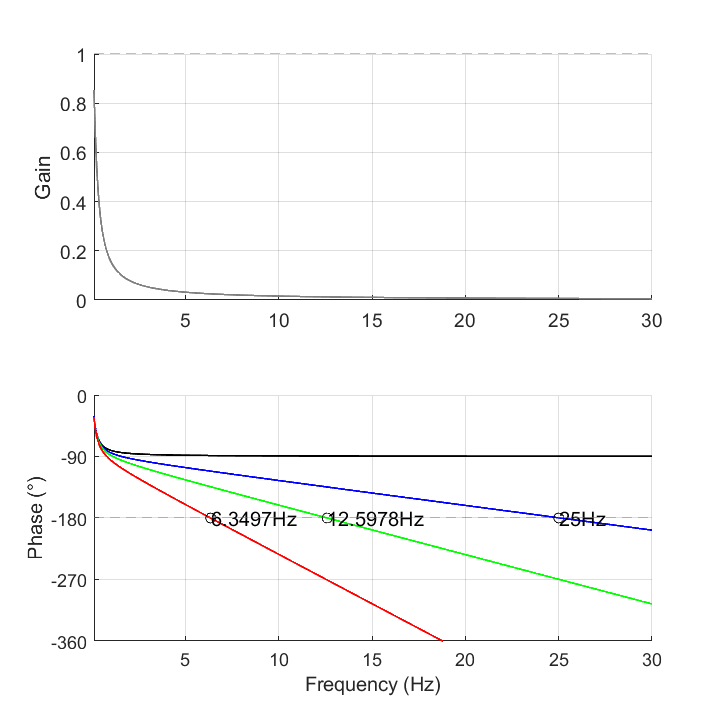

axes(ax(2)) ; hold on
plot([0 100],[-180 -180],'--','Color',[0.5 0.5 0.5])
linkaxes(ax,'x')
ax(1).YLabel.String = 'Gain';
ax(2).YLabel.String = ['Phase (' char(176) ')'];
ax(2).XLabel.String = 'Frequency (Hz)';
ax(2).YLim = [-(360*1) 0];
ax(2).YTick = (-360*5):90:90;
set(ax,'XLim',[0.1 30])
% set(ax,'XScale','log')

axes(ax(1)) ; hold on ; grid on
plot(freq,1*ones(length(freq),1),'--','Color',[0.5 0.5 0.5])

axes(ax(2)) ; hold on ; grid on
plot(freq,-180*ones(length(freq),1),'--','Color',[0.5 0.5 0.5])

% fig(2).Visible = 'on';

# *Drosophila* Body dynamics with head

clearvars -except HeadFree tf1 tf2 tf3 tf4
close all; clc

Body Inertia

% I = 5.2e-13; % Body Interia [N*m*s^2]
I_b = 5.9e-13; % Body Interia [N*m*s^2] +- 3.3e-14

Body Damping

% C = 5.2e-13; % Body Damping [N*m*s]
C_b = 1.1e-12; % Body Damping [N*m*s] +- 2.3e-11

Time Constant

tau = I_b/C_b; % time constant

Body Plant

G = tf(1,[tau 1]);
G.OutputDelay = 40e-3;

Head Inertia

I_h = 0.2*I_b;

Head Natural Frequency (rad/s)

wn = 50;

Head stiffness (N*m/rad)

K_h = wn^(2)*I_b;

Head critical damping (N*m*s/rad)

cc = 2*sqrt(K_h*I_b);
z = 1.2;

Head damping (N*m*s/rad)

C_h = z*cc;

Head Plant

P = tf(1,[I_h C_h K_h]);

Head Controller

Ctrl = 1;

Reference to Error

% R2E = tf(tf4)
R2E = 678000000*(1/(1+P*Ctrl));
R2E.IODelay = 10e-3


R2E =
 
                    8e-05 s^2 + 0.048 s + 1
  exp(-0.01*s) * -----------------------------
                 1.18e-13 s^2 + 7.08e-11 s + 1
 
Continuous-time transfer function.



Reference to Body

R2B = R2E*G


R2B =
 
                           8e-05 s^2 + 0.048 s + 1
  exp(-0.05*s) * --------------------------------------------
                 6.329e-14 s^3 + 3.809e-11 s^2 + 0.5364 s + 1
 
Continuous-time transfer function.



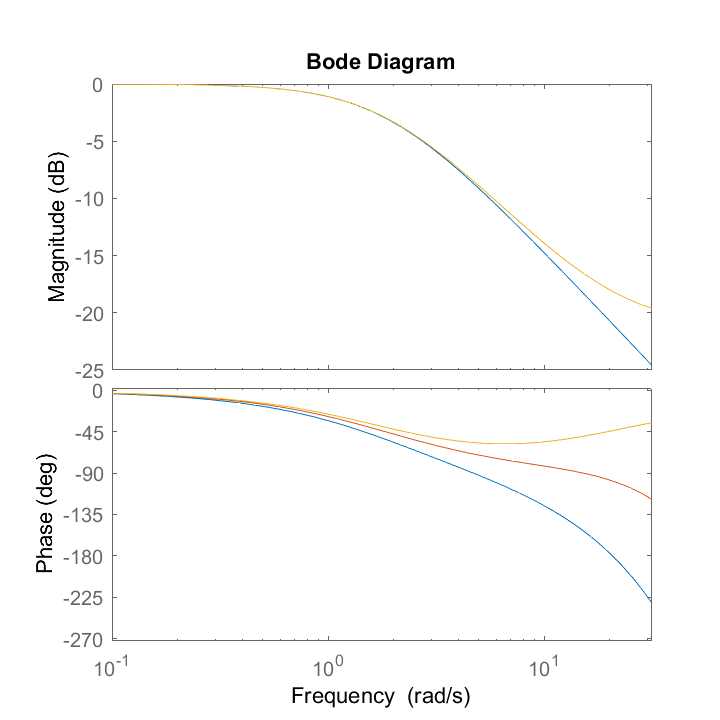

fig(1) = figure (1); clf
fig(1).Units = 'inches';
fig(1).Position = [2 2 5 5];
hold on

G.IODelay = 40e-3;
bode(G)
bode(R2B)
R2B.IODelay = 4e-3;
bode(R2B)
xlim(10.^[-1 1.5])